# Using pcolor and imagesc

Instructions are in the task pane to the left. Complete and submit each task one at a time. This code creates a grid.

x = -1:0.1:1;
y = -1:0.1:1;
[X,Y] = meshgrid(x,y);
Z = X.^2 + Y.^2;

## Task 1

The `pcolor` function has the same syntax as `surf`. In fact, it actually creates a flat surface with `ZData` all set to 0 and `CData` set to `Z`.

`pcolor``(``X``,``Y``,``Z``)`

**TASK1**

Create a flat surface plot of the z-data over the entire XY grid and assign the output to a variable with the name `s`.

**Hint1**

The `pcolor` function can be used to create a flat surface.

`s` `=` `pcolor``(``xMatrix``,``yMatrix``,``zMatrix``)`

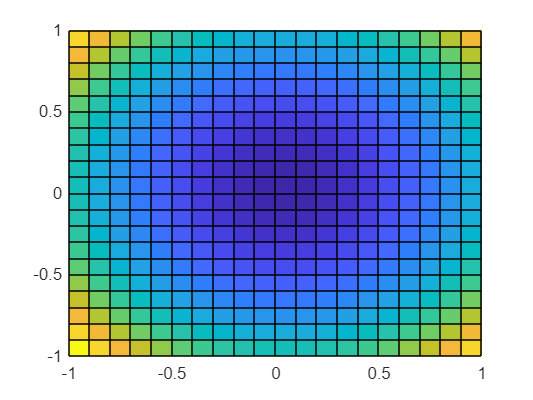

s =   Surface with properties:

       EdgeColor: [0 0 0]
       LineStyle: '-'
       FaceColor: 'flat'
    FaceLighting: 'flat'
       FaceAlpha: 1
           XData: [21×21 double]
           YData: [21×21 double]
           ZData: [21×21 double]
           CData: [21×21 double]

  Show all properties


s=pcolor(X,Y,Z)

## Task 2

Because this is a surface object, you can customize its appearance by modifying properties in the same way you would a surface plot.

**TASK2**

Change the grid line alpha value to 0.2. Then change the color data of the faces to be interpolated

**Hint2**

Use the `EdgeAlpha` property of `s` to change the grid line transparency.

`s.EdgeAlpha` `=` `0.5`

Use the `FaceColor` property of `s` to change the face color values.

`s.FaceColor` `=` `'interp'`

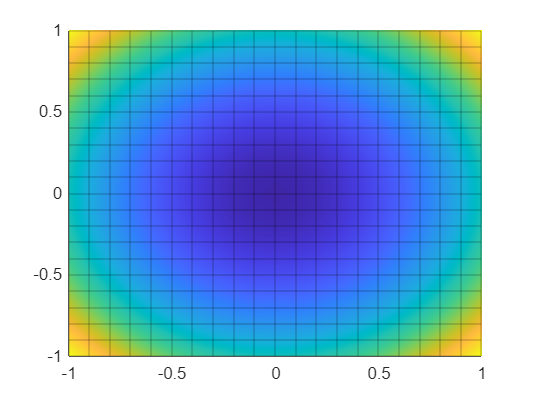

s.EdgeAlpha = 0.2;
s.FaceColor = "interp";

## Task 3

The `imagesc` function displays each element of a matrix as a single color based on the element value. The result is an image object. If you just give a single matrix as input, the result will be an *indexed image*.

`imagesc``(``Z``)`

**TASK3**

Create an indexed image from `Z` and assign the output to a variable with the name `im`.

**Hint3**

The `imagesc` function displays a scaled color image.

`imagesc``(``zMatrix``)`

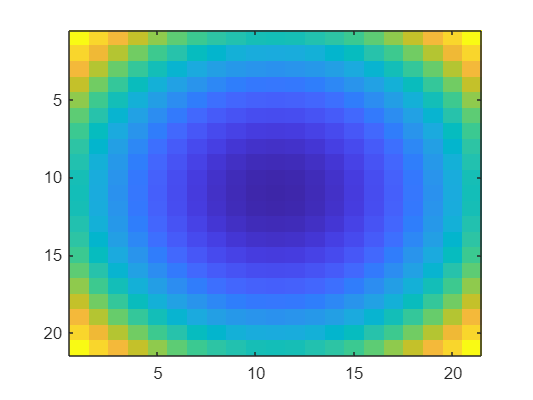

im = imagesc(Z);

## Task 4

By default, the *x*- and *y*-axis range of an image spans the number of rows and columns of the matrix, respectively. If you give *x* and *y* data as input, it must be in the form of a vector, not a matrix. It can even be a two-element vector of range values.

`imagesc``([``0` `1``]``,``[``-2` `2``]``,``Z``)`

**TASK4**

Create an indexed image from `Z` with appropriate values for *x* and *y* ranges. Assign the output to a variable with the name `im2`.

**Hint4**

The `imagesc` function displays a scaled color image.

`imagesc``([``xMin` `xMax``]``,``[``yMin` `yMax``]``,``zMatrix``)`

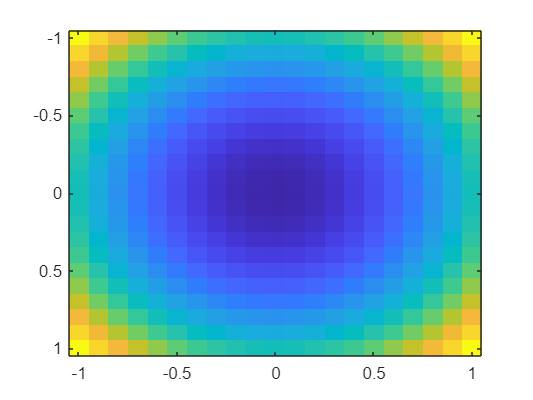

im2 = imagesc([-1 1],[-1 1],Z);